selected_date=1

selected_date = 1

selected_svm=1

selected_svm = 1

c=1e-4%正則化項についている

c = 1.0000e-04

l=6;%分割数ここを大きくするとより細かく分類
%cが大きい（罰則が緩い)と青点(ラベル１でx2方向の値が大きくなってくれる。
rng(1);
%cの値で誤答率がどう変化するか
% クラス毎の点の数
numPoints = 100;
m=numPoints*2;
randomPoints1 = zeros(numPoints, 2); 
randomPoints2 = zeros(numPoints, 2); 

if selected_date==6
center_point_ab_1=4;
center_point_ab_2=4;
radius=5;

theta1 = 2 * pi * rand(numPoints, 1);        % 角度
r1 = [radius * sqrt(rand(numPoints/2, 1)); radius * 0.6 * sqrt(rand(numPoints/2, 1))];

x1 = -1*center_point_ab_1 + r1(1:numPoints/2) .* cos(theta1(1:numPoints/2));                 % x座標
y1 = center_point_ab_1 + r1(1:numPoints/2) .* sin(theta1(1:numPoints/2));

x1_ = center_point_ab_1 + r1(numPoints/2+1:end) .* cos(theta1(numPoints/2+1:end));                 % x座標
y1_ = -1*center_point_ab_1 + r1(numPoints/2+1:end) .* sin(theta1(numPoints/2+1:end));
% y座標

theta2 = 2 * pi * rand(numPoints, 1);
r2 = [radius * sqrt(rand(numPoints/2, 1)); radius * 0.6 * sqrt(rand(numPoints/2, 1))];
x2 = center_point_ab_2 + r2(1:numPoints/2) .* cos(theta2(1:numPoints/2));
y2 = center_point_ab_2 + r2(1:numPoints/2) .* sin(theta2(1:numPoints/2));

x2_ = -1*center_point_ab_2 + r2(numPoints/2+1:end) .* cos(theta2(numPoints/2+1:end));                 % x座標
y2_ = -1*center_point_ab_2 + r2(numPoints/2+1:end) .* sin(theta2(numPoints/2+1:end));

randomPoints1=[x1,y1;x1_,y1_];
randomPoints2=[x2,y2;x2_,y2_];
dateset{6}=[randomPoints1;randomPoints2];
end

if selected_date == 5
    % パラメータ設定
    numTurns = 2;  % スパイラルの巻き数
    noise = 0.2;   % ノイズ量（小さめ）

    % クラスタ1（スパイラル1）
    t1 = linspace(0, numTurns * 2 * pi, numPoints)';
    r1 = linspace(0.5, 5, numPoints)';
    x1 = r1 .* cos(t1) + noise * randn(numPoints,1);
    y1 = r1 .* sin(t1) + noise * randn(numPoints,1);

    % クラスタ2（スパイラル2）: 位相をπだけずらして反対側に巻く
    t2 = linspace(0, numTurns * 2 * pi, numPoints)' + pi;
    r2 = linspace(0.5, 5, numPoints)';
    x2 = r2 .* cos(t2) + noise * randn(numPoints,1);
    y2 = r2 .* sin(t2) + noise * randn(numPoints,1);

    randomPoints1 = [x1, y1];
    randomPoints2 = [x2, y2];
    
    dateset{5} = [randomPoints1; randomPoints2];
end

if selected_date == 4
    t = linspace(0, 1, numPoints)';  % パラメータ（0〜1）
    t = t + 0.1 * randn(numPoints,1);  % 少しノイズを追加
    
    % S字カーブの中心線
    x1 = 20 * t - 10;  % x: -10〜10にスケーリング
    y1 = 5 * sin(2 * pi * t);  % y: S字型
    
    % クラスタ1: 中心線に沿った点（少しノイズ）
    x1 = x1 + 0.5 * randn(numPoints, 1);
    y1 = y1 + 0.5 * randn(numPoints, 1);
    
    % クラスタ2: S字の上下にオフセット（別カーブに沿う）
    x2 = x1 + 1.5 * randn(numPoints, 1);  % xをずらす
    y2 = y1 + sign(sin(2 * pi * t)) .* (2 + 0.5 * randn(numPoints, 1)); % 上下に離す
    
    randomPoints1 = [x1, y1];
    randomPoints2 = [x2, y2];
    
    dateset{4} = [randomPoints1; randomPoints2];
end


if selected_date==3
center_point_ab_1=2.5;
radius=5;
theta1 = 2 * pi * rand(numPoints, 1);        % 角度
r1 = radius * sqrt(rand(numPoints, 1));      % 半径（均等分布）
x1 = -1*center_point_ab_1 + r1 .* cos(theta1);                 % x座標
y1 = center_point_ab_1 + r1 .* sin(theta1);                  % y座標

theta2 = 2 * pi * rand(numPoints, 1);
r2 = radius * sqrt(rand(numPoints, 1));
x2 = center_point_ab_1 + r2 .* cos(theta2);
y2 = -1*center_point_ab_1 + r2 .* sin(theta2);

randomPoints1=[x1,y1];
randomPoints2=[x2,y2];
dateset{3}=[randomPoints1;randomPoints2];
end

if selected_date==2
radius = 5; % 円の半径
center = [0, 0.5]; % 円の中心
%内部の点
for i = 1:numPoints
    angle = 2 * pi * rand();          % ランダムな角度
    r = radius * sqrt(rand());        % 半径を均一分布にするため sqrt
    x = center(1) + r * cos(angle);
    y = center(2) + r * sin(angle);
    randomPoints1(i, :) = [x, y];
end

% 外側の点
for i = 1:numPoints
    angle = 2 * pi * rand();          % ランダムな角度
    r = radius + (10 - radius) * rand(); % 半径以上〜10の間に分布
    x = center(1) + r * cos(angle);
    y = center(2) + r * sin(angle);
    randomPoints2(i, :) = [x, y];
end
dateset{2}=[randomPoints1;randomPoints2];
end

if selected_date==1

for i=1:numPoints
    randomPoints1(i, 1) = -10+20*rand();
    X=randomPoints1(i,1);
    fun = 7/1800* X^3-7/200*X^2-7/180*X ;
    randomPoints1(i,2)=-10+(fun+10)*rand();
    
    randomPoints2(i, 1) = -10+20*rand();
    X=randomPoints2(i,1);
    fun = 7/1800* X^3-7/200*X^2-7/180*X ;
    randomPoints2(i,2)=fun+(10-fun)*rand();

end
dateset{1}=[randomPoints1;randomPoints2];
end


    
x=dateset{selected_date};% ランダムポイントの生成
y=[ones(m/2,1);-ones(m/2,1)];


x1=x(:,1);
x2=x(:,2);

p=l;
m=200;%データ数
%p=l,beta=l-2
switch selected_svm
    case 1
        [score,score_axis,alpha,b,n] = nonliner_svm_v0513(x,y,c,l);
    case 2
        [score,score_axis,alpha,b,n] = w_min_spline_svm_v0513(x,y,c,l);
end


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

   -6.0225   -2.0473    1.9279    5.9031


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 600             
  Affine conic cons.     : 1 (602 rows)
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 614             
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 400
Eliminator terminated.
Eliminator started.
Freed constraints in elimi


alpha_=reshape(alpha,n,p);

for i = 1:n
    fprintf("alpha_%d: ", i);        
    fprintf("%g ", alpha_(i, :));    
    fprintf("\n");                   
end

alpha_1: 

2.7356 0.0219074 -0.160221 -0.147917 0.29264 0.288357 

alpha_2: 

-1.35712 0.00562789 -0.225434 -0.0422831 1.0634 -1.00284 

fprintf("b:%g", b);

b:16.1975


tiledlayout(3,3)%出力グラフのエリアを９分割
nexttile(2,[1,2]);%上段、左から２番目から、一行２列のタイルにプロット
plot(-10:10, arrayfun(@(x1) score_axis(x1,1), -10:10), 'k');

nexttile(4,[2,1]);
plot(arrayfun(@(x2) score_axis(x2,2), -10:10), -10:10, 'k');
yticks([-10,-5,0,5,10]);

nexttile(5,[2,2]);
hold on;

scatter(x(y>0,1),x(y>0,2));%y>0であれば、xの行、列の座標を返す
scatter(x(y<0,1),x(y<0,2));

g = @(x1,x2) score(x1,x2);

fcontour(g, [-10,10,-10,10], 'k-', 'LevelList', 0, 'MeshDensity',200);

%マージン境界
%fcontour(g, [-10,10,-10,10], 'k--', 'LevelList', [-1,1], 'MeshDensity',200);
% 紫（値 = -1）の等高線を描画
fcontour(g, [-10,10,-10,10], 'LineStyle', '--', 'LineColor', [0.5 0 0.5], 'LevelList', -1, 'MeshDensity', 200);


% 緑（値 = 1）の等高線を描画
fcontour(g, [-10,10,-10,10], 'LineStyle', '--', 'LineColor', [0 0.6 0], 'LevelList', 1, 'MeshDensity', 200);

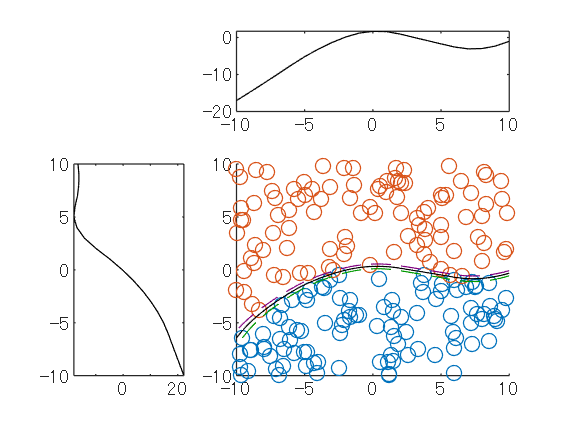


hold off;

%iscollect = sum((y.*score([x1,x2]))>0);
 %disp(iscollect);
 %disp(['分類成功率 ' num2str(iscollect/200*100) '% ']);


y_pre=g(x(:,1),x(:,2));
count_error = sum(y.*y_pre < 0);
disp(['誤答率：', sprintf('%.2f', count_error/m*100), '%']);

誤答率：0.00%
